# Diagrama de Moody

### Contexto

El **diagrama de Moody** es una herramienta gráfica que se usa para determinar el **coeficiente de fricción** en el flujo de fluidos a través de tuberías. Este coeficiente de fricción es clave en el cálculo de la pérdida de energía debida a la fricción en el flujo de un fluido.

El diagrama se basa en la **ecuación de Colebrook-White** que relaciona el coeficiente de fricción $f$, el número de Reynolds $Re$, y la rugosidad relativa $\frac{\varepsilon}{D}$:


$$\frac{1}{\sqrt{f}} = -2\log{\left( \frac{\varepsilon/D}{3.7} + \frac{2.51}{Re\sqrt{f}}\right)}$$


El diagrama facilita la interpretación del comportamiento del flujo laminar, transitorio y turbulento para distintos valores de Reynolds y rugosidad.

El diagrama de Moody esperado es similar al siguiente:

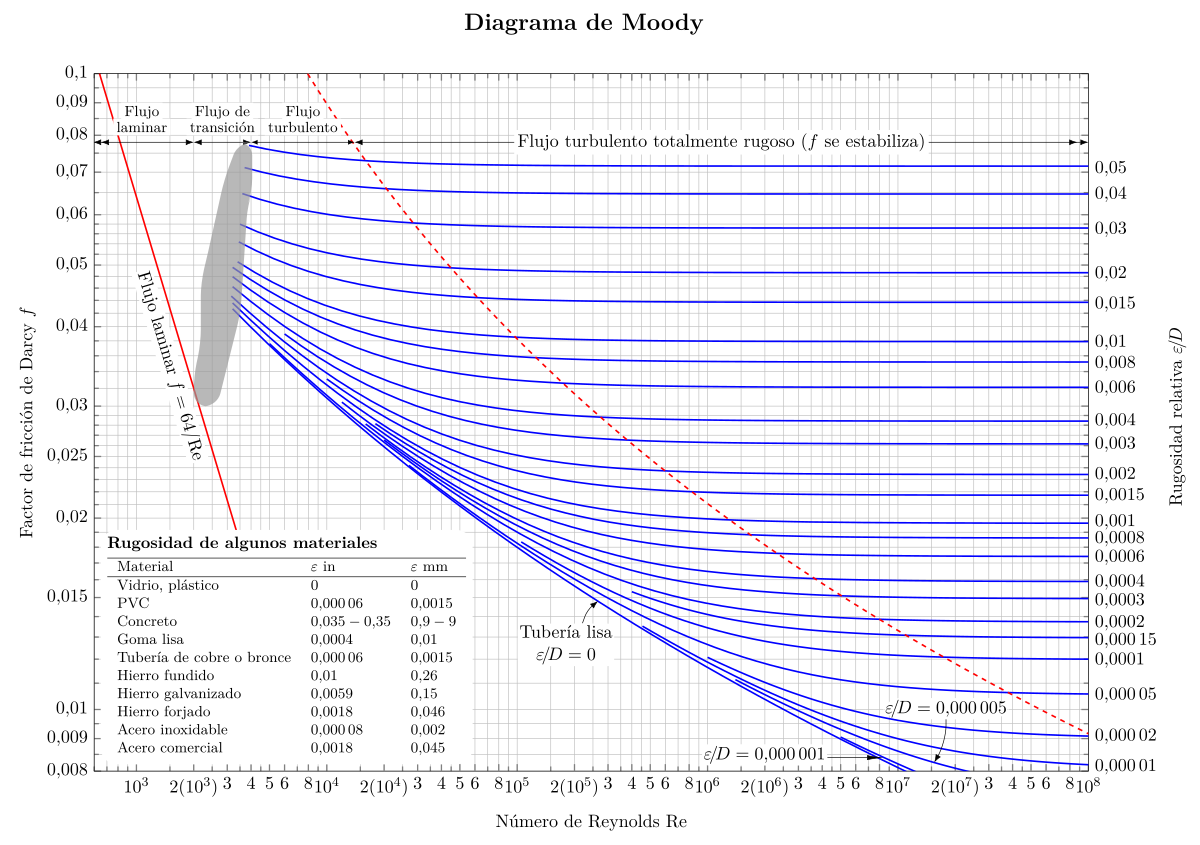

No obstante, **sólo se recomienda el uso de la función para fines académicos, no para fines prácticos.** Debido al gran avance de la tecnología y muchas herramientas asociadas, especialmente la programación, es obsoleto el uso del diagrama fuera del ámbito académico. Si se desea determinar el coeficiente de fricción $f$, es mejor utilizar alguna de las otras funciones detalladas en este documento.

### Aplicación

help fnc_diagrama_moody

 fnc_diagrama_moody   Generar el diagrama de Moody.
   fnc_diagrama_moody(parametros)

    Entradas:
    
       Rugosidad_relativa {escalar | vector}: Rugosidad relativa del fluido.
    
    Salidas:
    
       Gráfica del diagrama de Moody.
    
    Documentation for fnc_diagrama_moody



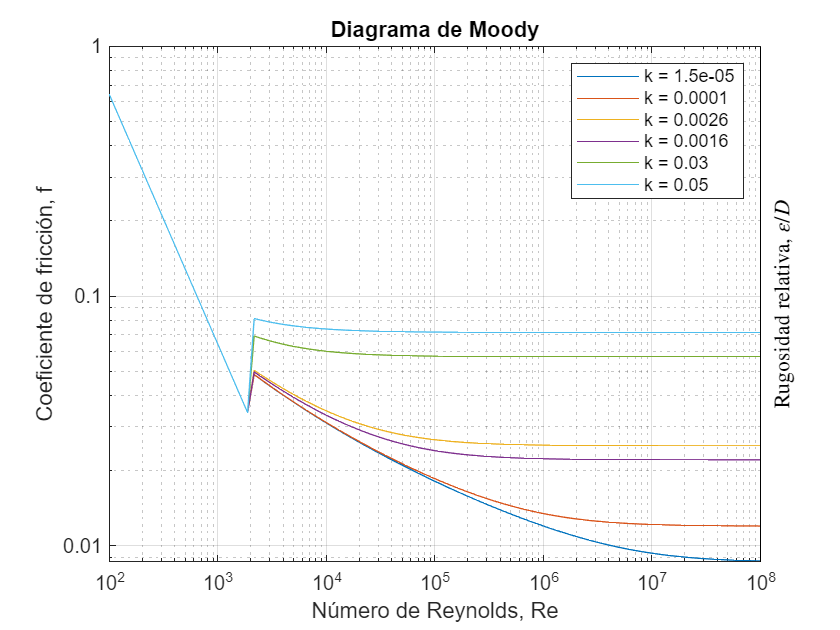

% Entradas
D = 100;                            % Diamétro [mm]
k = [0.0015 0.01 0.26 0.16 3 5];    % Rugosidad absoluta [mm]

% Procedimiento y resultado
kD = k / D;
fnc_diagrama_moody("Rugosidad_relativa", kD)